clc;
clear;

## Discretização do Modelo

% Parâmetros do sistema de umidade
Kh = 13.2;
Khta = 1.0;
tau_h = 22.0;
Khu2 = 10.0;
tau_hu2 = 18.7;
Ktau1 = 4.5;
pole_tau1 = 1.0;

% Definindo o período de amostragem Ts
Ts = tau_h / 10;

% Número de passos para a resposta ao impulso
steps = 50;

% Funções de transferência contínuas
clear tf;
s = tf('s');
H_U1_cont = Kh * (Khta / Ktau1) / ((tau_h * s + 1) * (s + pole_tau1));
H_U2_cont = -Khu2 / (tau_hu2 * s + 1);

% Discretização
H_U1_disc = c2d(H_U1_cont, Ts, 'zoh');
H_U2_disc = c2d(H_U2_cont, Ts, 'zoh');

## Resposta ao Impulso

% Obtendo a resposta ao impulso
[impulse_U1, ~] = impulse(H_U1_disc, 0:Ts:Ts*(steps-1));
[impulse_U2, ~] = impulse(H_U2_disc, 0:Ts:Ts*(steps-1));

% Definindo os horizontes de predição (N) e de controle (M)
N = 20;  % Horizonte de predição
M = 5;   % Horizonte de controle

% Construindo a matriz de predição G para U1
G_U1 = toeplitz(impulse_U1(1:N), [impulse_U1(1), zeros(1, M-1)]);

## Cálculo da Ação de Controle

% Setpoint e distúrbio inicial
r = ones(N, 1) * 0.5;  % Setpoint desejado para umidade
d = zeros(N, 1);       % Sem distúrbio inicial

% Parâmetro de penalidade lambda (ajustável)
lambda = 0.01;
I = eye(M);

% Calculando a ação de controle ΔU
dU = (G_U1' * G_U1 + lambda * I) \ (G_U1' * (r - d));

## Simulação do Sistema Controlado

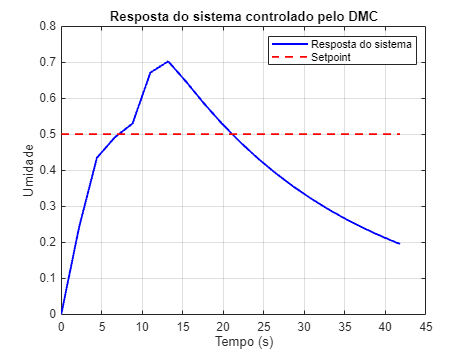

% Simulando o comportamento do sistema controlado
y = G_U1 * dU + d;

% Exibindo os resultados
figure;
plot(0:Ts:(N-1)*Ts, y, 'b', 'LineWidth', 1.5);
hold on;
plot(0:Ts:(N-1)*Ts, r, 'r--', 'LineWidth', 1.5);
xlabel('Tempo (s)');
ylabel('Umidade');
legend('Resposta do sistema', 'Setpoint');
title('Resposta do sistema controlado pelo DMC');
grid on;